clc; clear;
u = symunit;
CP = py.importlib.import_module("CoolProp.CoolProp");


% Rør info
D = 8*u.mm;
D_t = 0.2*u.mm;
D_u = D;
D_i = D_u - D_t;

% Lamel info
B_kond = 36.5*u.cm;

H = 30*u.cm;
B = 6.5*u.cm;
N = 54; % antal huller
N_lam = 145;
lam_t = unitConvert(0.025*u.mm,"SI");

lam_mel = 3*u.mm;
h_lam_luft = 3*u.mm;

lam_t_tot = vpa(N_lam*lam_t,3)

$$lam\_t\_tot = 0.00362\,m$$


vpa(unitConvert(H*B,"SI"))

$$ans = 0.0195\,m^{2}$$

% Lamel areal og effektiv lamel radius
syms r_2eff

A_lam = 2*(H*B - N*pi/4 * D^2);
A_lam = vpa(unitConvert(A_lam,"SI"),4)

$$A\_lam = 0.03357\,m^{2}$$


A_lam2 = 2*N*pi*(r_2eff^2 - (D/2)^2);
A_lam2 = vpa(unitConvert(A_lam2,"SI"),4);

r_2eff_num = A_lam2 == A_lam;

r_2eff_num = solve(r_2eff_num, r_2eff);
r_2eff_num = vpa(unitConvert(r_2eff_num,"SI"),4)

$$r\_2eff\_num = \left(\begin{array}{c} -0.01072\,m\\ 0.01072\,m \end{array}\right)$$


% Lufteksponeret areal af rør
A_b = (B_kond - lam_t_tot) * D * N;
A_b = vpa(unitConvert(A_b, "SI"), 3)

$$A\_b = 0.156\,m^{2}$$


% Total overfladeareal af finner
A_t = N_lam*A_lam + A_b;
A_t = vpa(A_t, 5)

$$A\_t = 5.024\,m^{2}$$


A_lam*N_lam/A_b

$$ans = 31.181332518017945757817527890341$$

% Luftstrømshastighed
rho_luft = CP.PropsSI("D","T",273.15 + 55,"P",101325,"air") * u.kg/u.m^3;% Luft ved 61.5C, fordi luften er 20 og r134 er 90 - filmtemp
A_1 = ((H-1*u.cm)/2)^2*pi;
A_3 = H*B_kond;
A_2 = lam_mel * h_lam_luft * N_lam; % mellemrummet mellem hver lamel, snævreste tværsnit luften kommer gennem, antal lameller
vpa(rho_luft,5)

$$ans = 1.0758\,\frac{\mathrm{kg}}{m^{3}}$$

%V_1 = 1*u.m/u.s;

syms V_2 V_1
V_3 = 8.8*u.km/u.h;
V_3 = vpa(unitConvert(V_3,"SI","Derived"),4)

$$V\_3 = 2.444\,\frac{m}{s}$$




eq1 = rho_luft*A_1*V_1;
eq2 = rho_luft*A_2*V_2;
eq3 = rho_luft*A_3*V_3;

eq_c1 = eq1 == eq3;
eq_c2 = eq2 == eq3;

c = solve([eq_c1,eq_c2], [V_1,V_2])

c = struct with fields:
    V_1: 4.0523636719091310912737075797547*([m]/[s])
    V_2: 2.0510855683276259832769289784048*(([cm]^2*[m])/([mm]^2*[s]))


c_1 = vpa(unitConvert(c.V_1, "SI", "derived"), 5)

$$c\_1 = 4.0524\,\frac{m}{s}$$

c_2 = vpa(unitConvert(c.V_2, "SI", "derived"), 5)

$$c\_2 = 205.11\,\frac{m}{s}$$


c2 = solve(eq_c2, V_2);
c2 = vpa(unitConvert(c2, "SI"), 5)

$$c2 = 205.11\,\frac{m}{s}$$


qm_luft1 = vpa(unitConvert(rho_luft*A_1*c_1,"SI","derived"),5)

$$qm\_luft1 = 0.28796\,\frac{\mathrm{kg}}{s}$$

qm_luft2 = vpa(unitConvert(rho_luft*A_2*c_2,"SI","derived"),5)

$$qm\_luft2 = 0.28796\,\frac{\mathrm{kg}}{s}$$

qm_luft3 = vpa(unitConvert(rho_luft*A_3*V_3,"SI","derived"),5)

$$qm\_luft3 = 0.28796\,\frac{\mathrm{kg}}{s}$$


qm_luft = qm_luft3;

% Varmeovergangstal for luftsiden
lambda_luft = vpa(CP.PropsSI("L","T",273.15 + 61.5,"P",101325,"air")*u.W/(u.m*u.K),4)

$$lambda\_luft = 0.02891\,\frac{W}{K\,m}$$

dyn_vis_luft = vpa(CP.PropsSI("V","T",273.15 + 61.5,"P",101325,"air")*u.Pa*u.s,4)

$$dyn\_vis\_luft = 2.017e-5\,\mathrm{Pa}\,s$$

kin_vis_luft = vpa(unitConvert(dyn_vis_luft/rho_luft,"SI","Derived"),3)

$$kin\_vis\_luft = 1.87e-5\,\frac{m^{2}}{s}$$


C = 0.38 % 5 stk forsatte

C = 0.3800


syms alpha_f

Nu = alpha_f*D/lambda_luft;

Re = vpa(unitConvert(c_2*D/kin_vis_luft, "SI"), 3)

$$Re = 8.75e+4$$


Nu2 = C*Re^(0.6)*(A_lam/A_b)^(-0.15);

alpha_f_eq = Nu == Nu2;

alpha_luft_num = solve(alpha_f_eq, alpha_f);
alpha_luft_num = vpa(unitConvert(alpha_luft_num, u.W/(u.m^2*u.K)), 6)

$$alpha\_luft\_num = 1596.51\,\frac{W}{K\,m^{2}}$$

% Lamel virkningsgrad
lambda_finne = 229 * u.W/(u.m*u.K);

m = sqrt((2*alpha_luft_num/(lambda_finne * lam_t)));
m = vpa(unitConvert(m, "SI"), 4)

$$m = 746.8\,\frac{1}{m}$$


r_1 = vpa(unitConvert(D/2,"SI"), 5)

$$r\_1 = 0.004\,m$$

r_2 = vpa(r_2eff_num(2), 5)

$$r\_2 = 0.010721\,m$$


C_2 = (2*r_1/m)/(r_2^2 - r_1^2);
C_2 = vpa(unitConvert(C_2, "SI"), 3)

$$C\_2 = 0.108$$




eta_f = C_2*(besselk(1, m*r_1)*besseli(1, m*r_2) - besseli(1, m*r_1)*besselk(1, m*r_2))/(besseli(0, m*r_1)*besselk(1, m*r_2) + besselk(0, m*r_1)*besseli(1, m*r_2));
eta_f = vpa(unitConvert(eta_f, "SI"), 5)

$$eta\_f = 0.1252$$



% Overordnet lamelvirkningsgrad

eta_lamel_total = 1 - (N_lam*A_lam/A_t)*(1 - eta_f);
eta_lamel_total = vpa(eta_lamel_total, 4)

$$eta\_lamel\_total = 0.1524$$

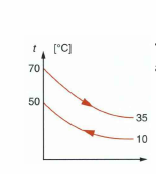

% Logaritmisk middel temperatur

t_fi = 90;    % Kølemiddel temp ind
t_fu = 30;    % Kølemiddel temp ud

t_lu = 27.57;    % Luft temp ud
t_li = 20;    % Luft temp inid

T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li))*u.K;
T_LM = vpa(T_LM, 4)

$$T\_LM = 28.63\,K$$

% Modstande
% Indvendig varmeovergangsmodstand

% A_i = pi*(D_i/2)^2;
% alpha_i = 1470 * u.W/(u.m^2*u.K); % r134a
% 
% R_i = 1/(alpha_i * A_i);
% R_i = vpa(unitConvert(R_i, u.K/u.W), 4)

% Fra overleaf
R_i = vpa((0.00391 * u.K/u.W),3)

$$R\_i = 0.00391\,\frac{K}{W}$$




% Varmeledningsmodstand i rørene
lambda_kobber = 372 * u.W/(u.m*u.K)

$$lambda\_kobber = 372\,\frac{W}{K\,m}$$

R_b = log(D_u/D_i)/(2*pi*D*lambda_kobber);
R_b = vpa(unitConvert(R_b, u.K/u.W), 4)

$$R\_b = 0.001354\,\frac{K}{W}$$


% Modstand for lamellerne og hele luftsiden

R_f = 1/(alpha_luft_num * A_t * eta_lamel_total);
R_f = vpa(unitConvert(R_f, u.K/u.W), 4)

$$R\_f = 0.0008182\,\frac{K}{W}$$


% Total modstand
R_tot = R_i + R_b + R_f

$$R\_tot = 0.0060821450409119074691932766624246\,\frac{K}{W}$$


% Vekslerens varmeydelse

Phi_veksler = T_LM/R_tot;
Phi_veksler = vpa(unitConvert(Phi_veksler, u.W), 10)

$$Phi\_veksler = 4706.796794\,W$$



cp_r134_ind = vpa(CP.PropsSI("C","T",273.15+90,"Q",1,"R134a") * u.J/(u.kg),3)

$$cp\_r134\_ind = 3120.0\,\frac{J}{\mathrm{kg}}$$

cp_r134_ud = vpa(CP.PropsSI("C","T",273.15+30,"Q",0,"R134a") * u.J/(u.kg),3)

$$cp\_r134\_ud = 1450.0\,\frac{J}{\mathrm{kg}}$$



qmr = 0.00338*u.kg/u.s

$$qmr = \frac{169}{50000}\,\frac{\mathrm{kg}}{s}$$


Er134_ind = vpa(unitConvert(qmr * cp_r134_ind,"SI","Derived"),3)

$$Er134\_ind = 10.5\,W$$

Er134_ud = vpa(unitConvert(qmr * cp_r134_ud,"SI","Derived"),3)

$$Er134\_ud = 4.89\,W$$




A_i = vpa(unitConvert(pi*(D_i/2)^2,"SI","Derived"),3)

$$A\_i = 4.78e-5\,m^{2}$$


D_r134_ind = vpa(CP.PropsSI("D","T",273.15+90,"Q",1,"R134a"),3) * u.kg/u.m^3

$$D\_r134\_ind = 216.7608496658504009246826171875\,\frac{\mathrm{kg}}{m^{3}}$$

D_r134_ud = vpa(CP.PropsSI("D","T",273.15-20,"Q",0,"R134a"),3)

$$D\_r134\_ud = 1360.0$$


Tlin = linspace(30,90,200);
Dlin = zeros(1,length(Tlin));



% Hastigheder gennem rør
vs_ind = unitConvert(qmr./(D_r134_ind.*A_i),"SI","Derived")

$$vs\_ind = 0.32632982557661753680599260595433\,\frac{m}{s}$$

ps = 100;
middel = "R134a";

h2 = 4.898*1e5;
p2 = 8.868*1e5;

h3 = 2.423*1e5;
p3 = p2;


%til plot


hlin2 = linspace(h2,h3,ps-1);


hs = [hlin2];


plin2 = linspace(p2,p3,ps-1);


pps = [plin2]/1e5;

Q_r134a = [];
Dqs = [];
Tqs = zeros(1,length(pps));

% Kvaliteter
for t = 1:length(pps)
    Qs = CP.PropsSI("Q","H",hs(t),"P",pps(t)*1e5, middel);

    if t < 50 && Qs == -1
        Qs = 1;
    elseif t > 50 && Qs == -1
        Qs = 0
    end

   % if Qs > -1 && Qs < 1
        Q_r134a(end+1) = Qs;
        Dqs(end+1) = CP.PropsSI("D","Q",Qs ,"P",pps(t)*1e5, middel);
        
   % else
    %    continue
    %end

    
end

Qs = 0

Qs = 0

Qs = 0


Q_r134a

Q_r134a =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9963    0.9813    0.9663    0.9512    0.9362    0.9212    0.9062    0.8912    0.8762    0.8611    0.8461    0.8311    0.8161    0.8011    0.7861    0.7710    0.7560    0.7410    0.7260    0.7110    0.6960


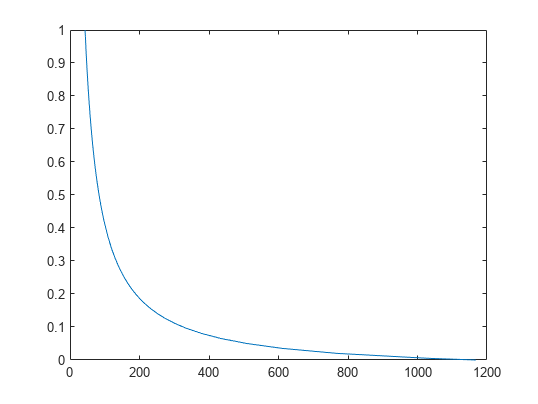


figure
plot(Dqs,Q_r134a)

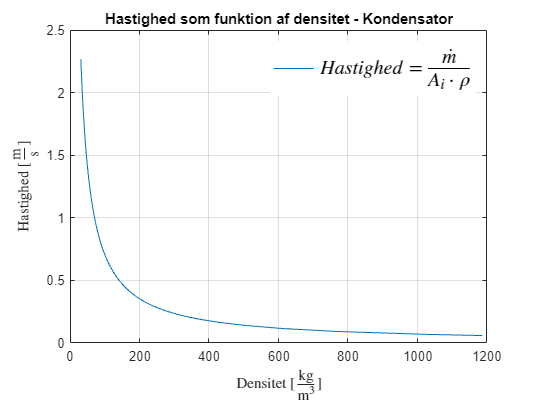



% Densiteter

D_r134a = zeros(size(pps));
for k = 1:length(pps)
    D_r134a(k) = CP.PropsSI("D","H",hs(k),"P",pps(k)*1e5, middel);
end

%D_r134a = D_r134a*u.kg/u.m^3;

vs_r134a = zeros(size(pps));

for h = 1:length(pps)
    vs_r134a(h) = separateUnits(qmr)/(D_r134a(h)*separateUnits(A_i));
end



%vs_r134a = vpa(unitConvert(vs_r134a,"SI","Derived"),3);


% Til plot
%vs_r134a_plot = separateUnits(vs_r134a);
%D_r134a_plot = separateUnits(D_r134a);


figure
T = table(D_r134a',vs_r134a');
writetable(T, "DensitetHastighedKondensator.txt")


plot(D_r134a, vs_r134a)


grid("on")
title("Hastighed som funktion af densitet - Kondensator")
xlabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")
ylabel("Hastighed [$\frac{\mathrm{m}}{\mathrm{s}}$]", "Interpreter","latex")

legend("$Hastighed = \frac{\dot{m}}{A_i \cdot\rho}$","Interpreter","latex","FontSize",15,"Box","off")

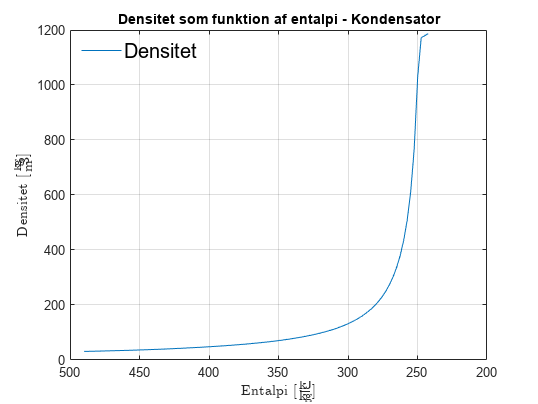



figure
plot(hs/1e3, D_r134a)

grid("on")
title("Densitet som funktion af entalpi - Kondensator")
xlabel("Entalpi [$\frac{\mathrm{kJ}}{\mathrm{kg}}$]","Interpreter","latex")
ylabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")

legend("Densitet","location","best","FontSize",15,"box","off")

set(gca, "XDir","reverse")

## Energi i løbet af kondensator

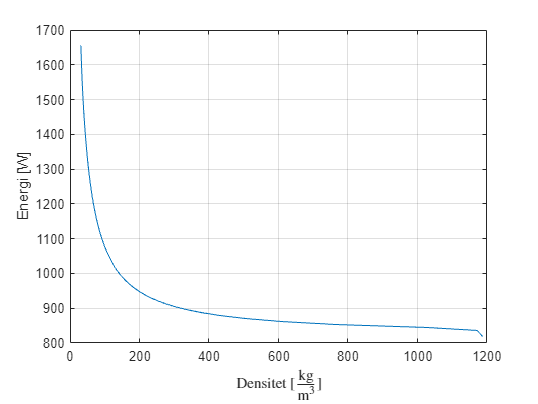

hs_units = hs.*u.J/u.kg;

Wkond = vpa(qmr.*hs_units,6);

Wkond_plot = separateUnits(Wkond);

figure
plot(D_r134a, Wkond_plot)

grid("on")
ylabel("Energi [W]")
xlabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")


kond_ror = vpa(unitConvert(B_kond * N,"SI","Derived"),4)

$$kond\_ror = 19.71\,m$$

vs_units = vpa(mean(vs_r134a)*u.m/u.s,4)

$$vs\_units = 1.152\,\frac{m}{s}$$


t_i_ror = kond_ror./vs_units

$$t\_i\_ror = 17.110422039908911319471944155234\,s$$



kond_hdiff = max(Wkond_plot) - min(Wkond_plot)

$$kond\_hdiff = 836.55000000000291038304567337036$$


kond_eff = kond_hdiff*(u.J/u.s).*t_i_ror

$$kond\_eff = 14313.723557485849562186464149921\,J$$


kond_eff = vpa(unitConvert(kond_eff,"SI","Derived"),4)

$$kond\_eff = 14310.0\,J$$

## Energiligninger


cp_r134_ind = vpa(CP.PropsSI("C","T",273.15+90,"Q",1,"R134a"),3)

$$cp\_r134\_ind = 3120.0$$

cp_r134_ud = vpa(CP.PropsSI("C","T",273.15+30,"Q",0,"R134a"),3)

$$cp\_r134\_ud = 1450.0$$


h_ind = max(hlin2);
h_ud = min(hlin2);

separateUnits(qmr)*separateUnits(cp_r134_ud)*(105 - (20))

$$ans = 415.5721372756779193878173828125$$

vpa(separateUnits(qmr)*(h_ud - h_ind),3)

$$ans = -837.0$$


% Modstande
% Indvendig varmeovergangsmodstand
syms  Tluftud

R_i = vpa((0.00391),3)

$$R\_i = 0.00391$$


% A_i = pi*(unitConvert(D_i,"SI")/2)^2;
% alpha_i = 1470; %* u.W/(u.m^2*u.K); % r134a
% 
% R_i = 1/(alpha_i * separateUnits(A_i));
% R_i = vpa(unitConvert(R_i, u.K/u.W), 4)

% Varmeledningsmodstand i rørene
lambda_kobber = 372% * u.W/(u.m*u.K);

lambda_kobber = 372


R_b = log(separateUnits(unitConvert(D_u,"SI"))/separateUnits(unitConvert(D_i,"SI")))/(2*pi*separateUnits(unitConvert(D,"SI"))*lambda_kobber);

% Modstand for lamellerne og hele luftsiden

R_f = 1/(separateUnits(alpha_luft_num) * separateUnits(A_t) * eta_lamel_total);


% Total modstand
R_tot = R_i + R_b + R_f;

% Logaritmisk middel temperatur

t_fi = 103;    % Kølemiddel temp ind
t_fu = 30;    % Kølemiddel temp ud

t_lu = Tluftud;    % Luft temp ud
t_li = 24;    % Luft temp inid

T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li));
T_LM = vpa(T_LM, 4);


cp_luft = vpa(CP.PropsSI("C","T",273.15 + 61.5,"P",101325,"air"),4);



phi_ydelse = vpa(separateUnits(T_LM)/R_tot,3);
phi_luft = vpa(separateUnits(qm_luft)*cp_luft*(t_lu - 20),3);
phi_fluid = vpa(separateUnits(qmr)*cp_r134_ind*(t_fu - 90),3);
phi_v = vpa(separateUnits(qmr)*(h_ud - h_ind),3);

eq = phi_ydelse == phi_luft - phi_fluid - phi_v;

Tluftud = solve(eq, Tluftud)

$$Tluftud = 30.109214224148077379080646426794$$